close all; clear;
%	Approximated based on hardware (DJI F-450 frame w/ 10in propellers) 
l = 0.23;
g = 9.81;
Kt = 0.02;
mass = 0.025;
Ixx = 4e-3;
Iyy = 4e-3;
Izz = 7e-3;
Ib = diag([Ixx Iyy Izz]);
d = -1e-3 * diag([1 1 1.75]);

## OG Controller sim

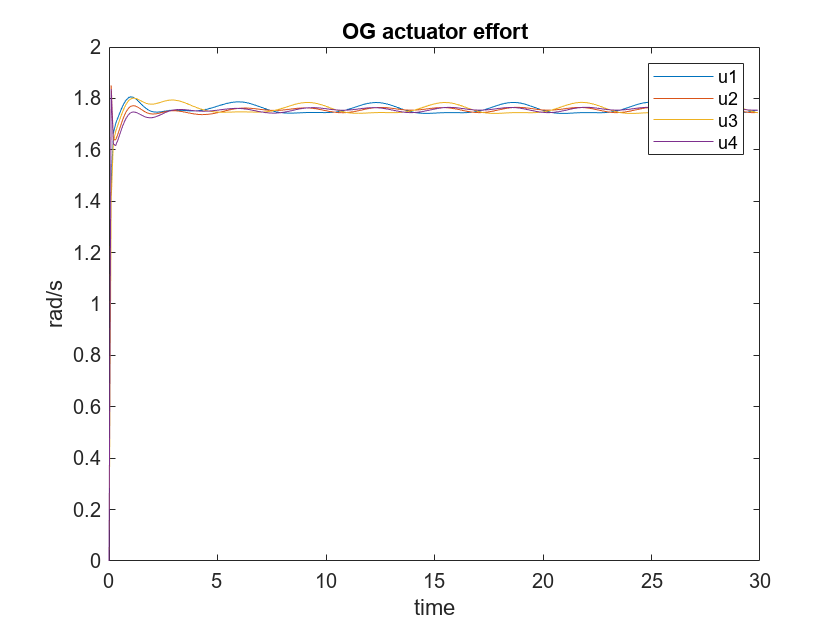


max_time = 30;
n_samples = max_time / 0.001;
t_space = linspace(0, max_time, n_samples);

dt = max_time / n_samples;

% histories
u_hist = zeros(4, n_samples);
r_hist = zeros(3, n_samples);
rdot_hist = zeros(3, n_samples);
rddot_hist = zeros(3, n_samples);
q_hist = zeros(3, n_samples);
qr_hist = zeros(3, n_samples);
omega_hist = zeros(3, n_samples);
omegadot_hist = zeros(3, n_samples);

qr_ext = [0 0 0 0 0 0 1 0 0 0 0 0; 0 0 0 0 0 0 0 1 0 0 0 0; 0 0 0 0 0 0 0 0 1 0 0 0];

% set initial conditions
r_r = [1; 0; 1];
r_hist(3, 1) = 1;
q_hist(1, 1) = -0.17;
q_hist(3, 1) = -0.6 * pi;
omega_hist(1, 1) = -0.1;
u_hist(:, 1) = zeros(4, 1);

for i = 1:(n_samples - 1)
	% step dynamics
	[dr, ddr, dq, do] = Rufous_Dynamics(rdot_hist(:,i), q_hist(:,i), omega_hist(:,i), u_hist(:,i), Kt, mass, g, l, Ib);

	% update control
	R = [r_r; 0; 0; 0; 0; 0; 0; 0; 0; 0];
	X = [r_hist(:, i); rdot_hist(:,i); q_hist(:,i); omega_hist(:,i)];
	[Kref, Kfb, Kff] = Rufous_og_controller(Kt, mass, g, [0; 0; 0], 40, 100, 0.1, 1, 10);

	% update states
	u_hist(:, i + 1) = Kff + (Kfb * Kref * (R - X));
	r_hist(:, i + 1) = r_hist(:, i) + (dr * dt);
	rdot_hist(:, i + 1) = rdot_hist(:, i) + (ddr * dt);
	q_hist(:, i + 1) = wrap_angle(q_hist(:, i) + (dq * dt));
	qr_hist(:, i + 1) = qr_ext * (Kref * (R - X));
	omega_hist(:, i + 1) = omega_hist(:, i) + (do * dt);

	% Sample Lyapunov
	V = Linearized_Lyapunov(r_r(3) - r_hist(3, i+1), rdot_hist(1, i+1), rdot_hist(2, i+1), rdot_hist(3, i+1), omega_hist(1, i+1), omega_hist(2, i+1), omega_hist(3, i+1), mass, Ib);

	if V > 1
		fprintf("Breaking for Lyapunov value %d at %i", V, i);
		fprintf("Omega %d %d %d", omega_hist(1, i), omega_hist(2, i), omega_hist(3, i));
		break;
	end

	if r_hist(3, i + 1) <= 0 % ground
		r_hist(3, i + 1) = 0;
		rdot_hist(3, i + 1) = max(0, rdot_hist(3, i + 1));
	end
end

figure
plot(t_space(1:100:end), max(u_hist(:, 1:100:end), [0; 0; 0; 0]))
title("OG actuator effort")
xlabel("time")
ylabel("rad/s")
legend("u1", "u2", "u3", "u4");

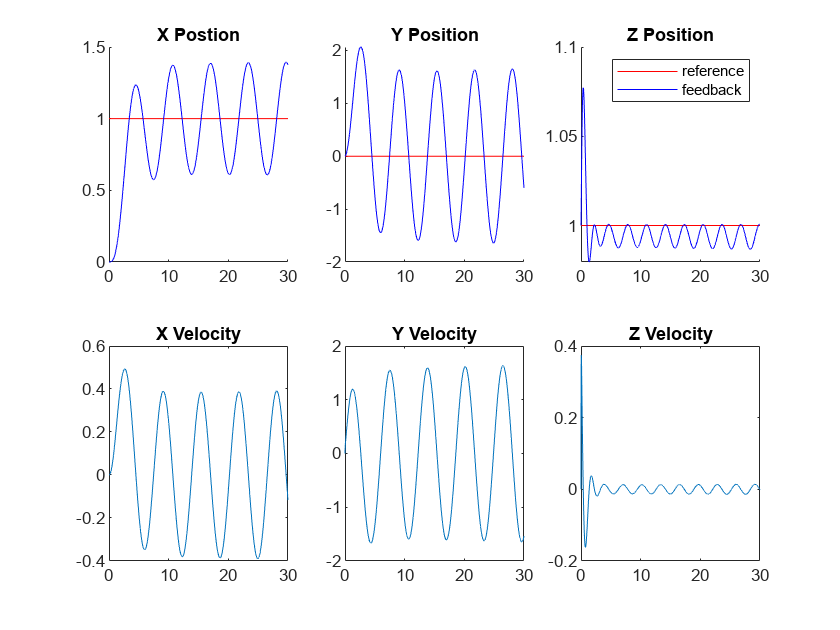


figure
title("OG Position history")
% draw_position_history(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r, 100);
position_titles = ["X Postion" "Y Position" "Z Position" "X Velocity" "Y Velocity" "Z Velocity"];
plot_vectors(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r, position_titles, 5);

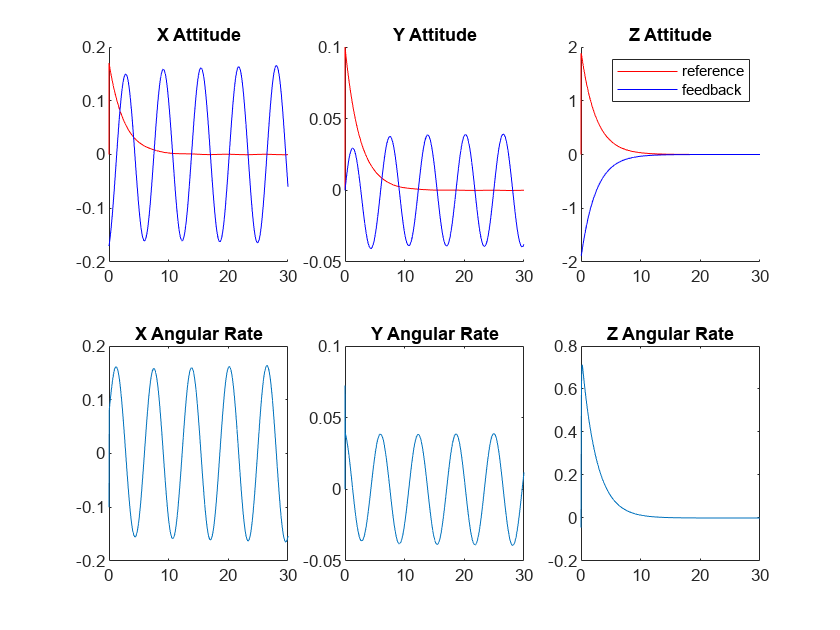


figure
title("OG Attitude history")
attitude_titles = ["X Attitude" "Y Attitude" "Z Attitude" "X Angular Rate" "Y Angular Rate" "Z Angular Rate"];
plot_vectors(t_space, q_hist, omega_hist, qr_hist, attitude_titles, 1);

## NL Controller sim

max_time = 10;
n_samples = max_time / 0.01;
t_space = linspace(0, max_time, n_samples);

dt = max_time / n_samples;

% histories
V_hist = zeros(n_samples);
u_hist = zeros(4, n_samples);
r_hist = zeros(3, n_samples);
rdot_hist = zeros(3, n_samples);
rddot_hist = zeros(3, n_samples);
q_hist = zeros(3, n_samples);
qr_hist = zeros(3, n_samples);
omega_hist = zeros(3, n_samples);
omegadot_hist = zeros(3, n_samples);

qr_ext = -[0 0 0 0 0 0 1 0 0 0 0 0; 0 0 0 0 0 0 0 1 0 0 0 0; 0 0 0 0 0 0 0 0 1 0 0 0];

% set initial conditions
r_r = [0; 0; 0];
% r_hist(3, 1) = 1;
% q_hist(1, 1) = pi/8; % [-pi/10 -pi/20 pi/20 pi/8] [unstable stable stable stable] 
q_hist(2, 1) = -pi/10; % [-pi/10 -pi/20 pi/20 pi/8] [stable stable stable unstable] 
% q_hist(3, 1) = -0.6 * pi;
omega_hist(1, 1) = -0.1;
u_hist(:, 1) = zeros(4, 1);

for i = 1:(n_samples - 1)
	% step dynamics
	[dr, ddr, dq, do] = Rufous_Dynamics(rdot_hist(:,i), q_hist(:,i), omega_hist(:,i), u_hist(:,i), Kt, mass, g, l, Ib);

	% update control
	R = [r_r; 0; 0; 0; 0; 0; 0; 0; 0; 0];
	X = [r_hist(:, i); rdot_hist(:,i); q_hist(:,i); omega_hist(:,i)];
	[Kref, Kfb, Kff] = Rufous_nl_controller(Kt, mass, g, [0; 0; 0], 100, 150, 0.0, 0.0, 0, 0);

	% update states
	u_hist(:, i + 1) = Kff + (Kfb * Kref * (R - X));
	r_hist(:, i + 1) = r_hist(:, i) + (dr * dt);
	rdot_hist(:, i + 1) = rdot_hist(:, i) + (ddr * dt);
	q_hist(:, i + 1) = wrap_angle(q_hist(:, i) + (dq * dt));
	qr_hist(:, i + 1) = qr_ext * (Kref * (R - X));
	omega_hist(:, i + 1) = omega_hist(:, i) + (do * dt);

	% Sample Lyapunov
	V = Linearized_Lyapunov(0, 0, 0, 0, omega_hist(1, i+1), omega_hist(2, i+1), omega_hist(3, i+1), mass, Ib);
	V_hist(i) = V;
	if V > 1e10
		fprintf("Breaking for Lyapunov value %d at %i", V, i);
		fprintf("Omega %d %d %d", omega_hist(1, i), omega_hist(2, i), omega_hist(3, i));
		break;
	end

	if r_hist(3, i + 1) <= 0 % ground
		r_hist(3, i + 1) = 0;
		rdot_hist(3, i + 1) = max(0, rdot_hist(3, i + 1));
	end
end

Breaking for Lyapunov value 4.865012e+12 at 6

Omega 1.486348e+03 -3.751679e+03 1.873343e+03

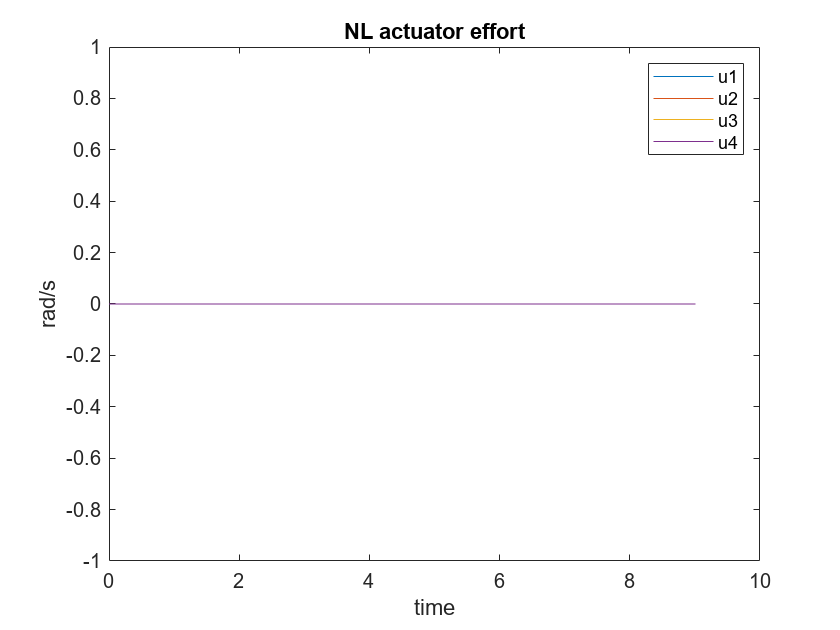


figure
plot(t_space(1:100:end), max(u_hist(:, 1:100:end), [0; 0; 0; 0]))
title("NL actuator effort")
xlabel("time")
ylabel("rad/s")
legend("u1", "u2", "u3", "u4");

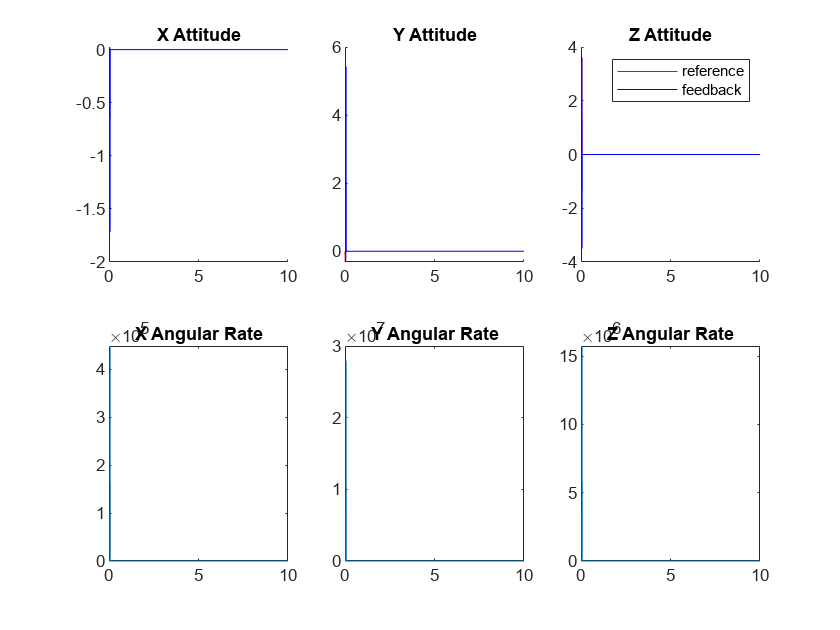


figure
title("NL Attitude history")
attitude_titles = ["X Attitude" "Y Attitude" "Z Attitude" "X Angular Rate" "Y Angular Rate" "Z Angular Rate"];
plot_vectors(t_space, q_hist, omega_hist, qr_hist, attitude_titles, 1);

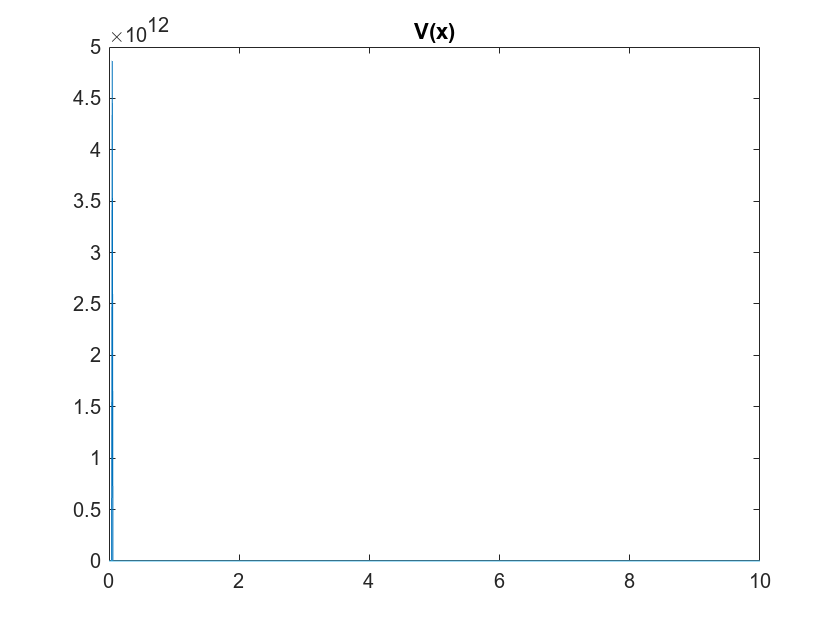


figure
plot(t_space, V_hist)
title("V(x)")

max_time = 30;
n_samples = max_time / 0.001;
t_space = linspace(0, max_time, n_samples);

dt = max_time / n_samples;

% histories
u_hist = zeros(4, n_samples);
r_hist = zeros(3, n_samples);
rdot_hist = zeros(3, n_samples);
rddot_hist = zeros(3, n_samples);
q_hist = zeros(3, n_samples);
qr_hist = zeros(3, n_samples);
omega_hist = zeros(3, n_samples);
omegadot_hist = zeros(3, n_samples);

qr_ext = -[0 0 0 0 0 0 1 0 0 0 0 0; 0 0 0 0 0 0 0 1 0 0 0 0; 0 0 0 0 0 0 0 0 1 0 0 0];

% set initial conditions
r_r = [10; 0; 10];
% r_hist(3, 1) = 1;
% q_hist(1, 1) = -0.17;
% q_hist(3, 1) = -0.6 * pi;
% omega_hist(1, 1) = -0.1;
u_hist(:, 1) = zeros(4, 1);

for i = 1:(n_samples - 1)
	% step dynamics
	[dr, ddr, dq, do] = Rufous_Dynamics(rdot_hist(:,i), q_hist(:,i), omega_hist(:,i), u_hist(:,i), Kt, mass, g, l, Ib);

	% update control
	R = [r_r; 0; 0; 0; 0; 0; 0; 0; 0; 0];
	X = [r_hist(:, i); rdot_hist(:,i); q_hist(:,i); omega_hist(:,i)];
	[Kref, Kfb, Kff] = Rufous_nl_controller(Kt, mass, g, [0; 0; 0], 40, 100, 0.01, 0.1, 3, 50);

	% update states
	u_hist(:, i + 1) = Kff + (Kfb * Kref * (R - X));
	r_hist(:, i + 1) = r_hist(:, i) + (dr * dt);
	rdot_hist(:, i + 1) = rdot_hist(:, i) + (ddr * dt);
	q_hist(:, i + 1) = wrap_angle(q_hist(:, i) + (dq * dt));
	qr_hist(:, i + 1) = qr_ext * (Kref * (R - X));
	omega_hist(:, i + 1) = omega_hist(:, i) + (do * dt);

	% Sample Lyapunov
	V = Linearized_Lyapunov(r_r(3) - r_hist(3, i+1), rdot_hist(1, i+1), rdot_hist(2, i+1), rdot_hist(3, i+1), omega_hist(1, i+1), omega_hist(2, i+1), omega_hist(3, i+1), mass, Ib);

	if V > 1e10
		fprintf("Breaking for Lyapunov value %d at %i", V, i);
		fprintf("Omega %d %d %d", omega_hist(1, i), omega_hist(2, i), omega_hist(3, i));
		break;
	end

	if r_hist(3, i + 1) <= 0 % ground
		r_hist(3, i + 1) = 0;
		rdot_hist(3, i + 1) = max(0, rdot_hist(3, i + 1));
	end
end

figure
plot(t_space(1:100:end), max(u_hist(:, 1:100:end), [0; 0; 0; 0]))
title("NL actuator effort")
xlabel("time")
ylabel("rad/s")
legend("u1", "u2", "u3", "u4");

figure
title("NL Position history")
% draw_position_history(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r, 100);
position_titles = ["X Postion" "Y Position" "Z Position" "X Velocity" "Y Velocity" "Z Velocity"];
plot_vectors(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r, position_titles, 5);

figure
title("NL Attitude history")
attitude_titles = ["X Attitude" "Y Attitude" "Z Attitude" "X Angular Rate" "Y Angular Rate" "Z Angular Rate"];
plot_vectors(t_space, q_hist, omega_hist, qr_hist, attitude_titles, 1);